# **DSIGPRO Lesson 1.1 in MATLAB**

clc;
clearvars;

## Signal Operations

### 0. Zero-padding

If signal a and b varies by length, returns updated a and b of equal length, with updated length that of the longer signal and zero as filler value.

% Demo of zeropad.m
x1 = [2 -1 1.5 1 2 0.5, 66]

x1 =     2.0000   -1.0000    1.5000    1.0000    2.0000    0.5000   66.0000


x2 = [-2 1 2 1 -1 1.5]

x2 =    -2.0000    1.0000    2.0000    1.0000   -1.0000    1.5000


t = -3:1:2;
fprintf('Length of x1: %.2f x2: %.2f',length(x1),length(x2))

Length of A: 7.00 B: 6.00


% Obviously a is bigger, so we make it even
[x1,x2] = zeropad(x1,x2,t)

x1 =     2.0000   -1.0000    1.5000    1.0000    2.0000    0.5000   66.0000


x2 =    -2.0000    1.0000    2.0000    1.0000   -1.0000    1.5000         0


fprintf('Length of x1: %.2f x2: %.2f',length(x1),length(x2))

Length of A: 7.00 B: 7.00

### 1. Adder

    x[n] = x1[n] + x2[n]

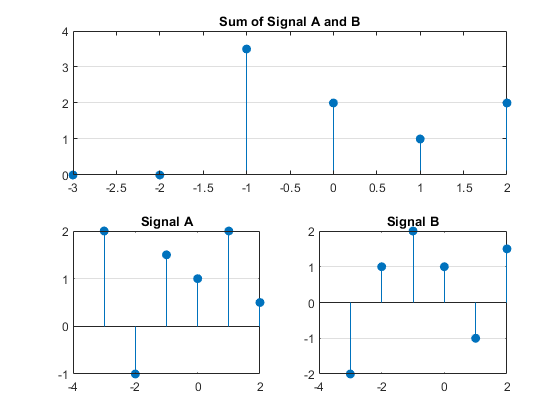

ans =          0         0    3.5000    2.0000    1.0000    2.0000


% Demo of sigsum.m
x1 = [2 -1 1.5 1 2 0.5];
x2 = [-2 1 2 1 -1 1.5];
t = -3:1:2;
% Plot
sigsum(x1,x2,t)

### 2. Multiplier

    x[n] = x1[n] x2[n]

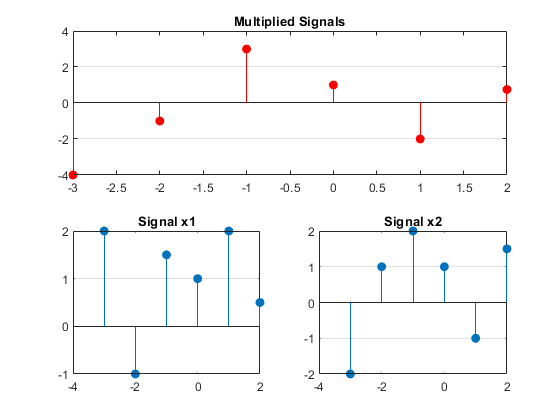

ans =    -4.0000   -1.0000    3.0000    1.0000   -2.0000    0.7500


% Demo of sigmul.m
x1 = [2 -1 1.5 1 2 0.5];
x2 = [-2 1 2 1 -1 1.5];
t = -3:1:2;
% Plot
sigmul(x1,x2,t)

### 3. Transformation of independent variable

#### 3.1 Shifting (too late chocolate)

    A signal x[n] maybe shifted in time by replacing the independent variable n by n – k, where k is an integer. If k is a positive integer, the time shift results in a delay of the signal by k units of time. If k is a negative integer, the time shift in an advance of the signal by k units in time.

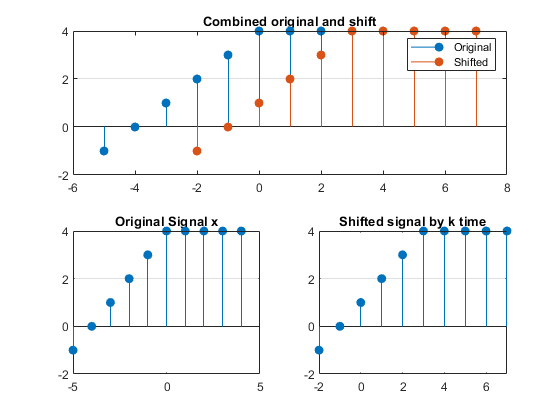

% Demo of sigshift.m
x1 = [-1 0 1 2 3 4 4 4 4 4];
t = -5:1:4;
n = 0;
k = 3;
newT = sigshift(x1,t,n,k,1);


% Compare old and new t values
fprintf('Value of old t');

Value of old t

t

t =     -5    -4    -3    -2    -1     0     1     2     3     4


fprintf('Value of new t');

Value of new t

newT

newT =     -2    -1     0     1     2     3     4     5     6     7


#### 3.2 Reversal

    The result of this operation is a folding or a reflection of the signal about the time origin n = 0.

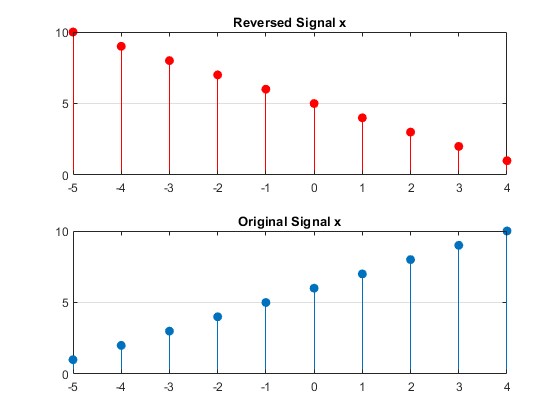

% Demo of sigrev.m
x1 = 1:10;
t = -5:1:4;
n = 3;
[r, newN] = sigrev(x1,t,n,1);


fprintf('Value of old n: %.2f', n);

Value of old n: 3.00

fprintf('Value of new n: %.2f', newN);

Value of new n: -4.00

#### 3.3 Time Scaling

    A third modification of the independent variable involves replacing n by μn where μ is an integer. This is also termed as down-sampling.

#### 3.4 TDFD / FDTD

    TD - Time delay / Shifting (see 3.1)

    FD - Fold / Reflect / Reversal (see 3.2)

    TDFD - Fold then delay **|** Reversal then shift               **x[-n + k]**

    FDTD - Delay then fold **| **Shift then reversal                **x[-n - k]**

% To do

### 4. 2-point Moving Average

    A third modification of the independent variable involves replacing n by μn where μ is an integer. This is also termed as down-sampling.

% Demo of sig2moveave.m
x1 = [2 -1 1.5 1 2 0.5]

x1 =     2.0000   -1.0000    1.5000    1.0000    2.0000    0.5000


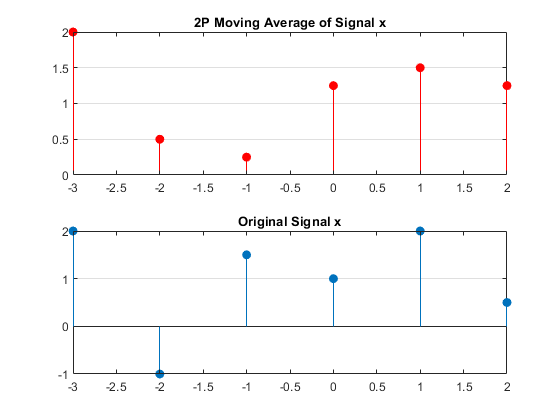

t = -3:1:2;
n = 0;
M = sig2moveave(x1,t,1);


% Compare old and new signal values
fprintf('Value of old signal');

Value of old signal

x1

x1 =     2.0000   -1.0000    1.5000    1.0000    2.0000    0.5000


fprintf('Value of new signal (moving average)');

Value of new signal (moving average)

M

M =     2.0000    0.5000    0.2500    1.2500    1.5000    1.2500
